## EMD Simulation

From "Photoreception and Vision in Invertebrates" by Buchner

clear;close all;clc
syms I_0 I_d lambda gamma(t) omega t phi phi_p tau

Spatial position

gamma(t) = phi - omega*t

$$gamma(t) = \varphi -\omega \,t$$

Luminance in 1st detetecor

I = I_0 + I_d*(sin((2*pi/lambda)*gamma))

$$I(t) = I_{0}+I_{d}\,\sin\left(\frac{2\,\pi \,\left(\varphi -\omega \,t\right)}{\lambda }\right)$$

Luminance in 2nd detetecor

Ip = subs(I,phi,phi+phi_p)

$$Ip(t) = I_{0}+I_{d}\,\sin\left(\frac{2\,\pi \,\left(\varphi +\varphi_{p}-\omega \,t\right)}{\lambda }\right)$$

Yc = I_d^(2)*((pi*tau*omega./lambda)/(1 + (2*pi*tau*omega./lambda).^(2)))*sin(2*pi*phi_p./lambda)

$$Yc = \frac{\pi \,{I_{d}}^{2}\,\omega \,\tau \,\sin\left(\frac{2\,\pi \,\varphi_{p}}{\lambda }\right)}{\lambda \,\left(\frac{4\,\omega^{2}\,\tau^{2}\,\pi^{2}}{\lambda^{2}}+1\right)}$$

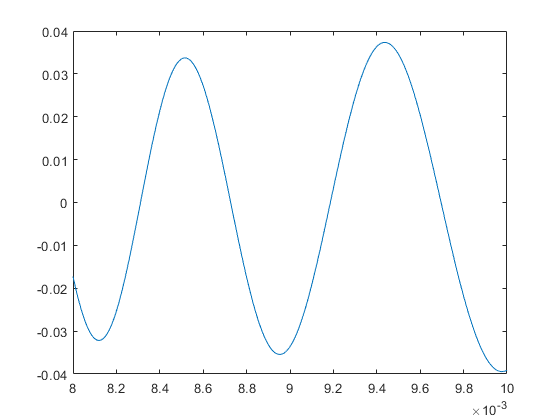

lambda_num = linspace(0.008,0.01,500)';
Yc_num = subs(Yc,{phi_p,tau,I_d,omega,lambda},{deg2rad(5),20e-3,1,1,lambda_num});
Yc_num = double(Yc_num);

figure (1) ; clf
plot(lambda_num,Yc_num)


% spatfreq_num = (1/phi_p)*[1];
% omega_num = 1./spatfreq_num;
% Yc_num = subs(Yc,{lambda,I_d,omega,tau,phi_p},{spatfreq_num,1,omega_num,1,deg2rad(5)})
% Yc_num = subs(Yc,{lambda,I_d,omega},{(1/phi_p)*[0.001, 1/4, 1/2, 3/4 , 1],1,1})


















